# Stability Follow-up

clear; close all; clc;
base_path = get_data_root();

base_path = '/Volumes/quattrocolo/crhip/ingvild/Analysis'

save_path = fullfile(base_path,'CompiledData');
path = fullfile(base_path,'Figures/Ingvild/Ephys/Stability/Quantification/KLd/OccupancyCorrected/RewardCells');
load(fullfile(save_path,'All_1D_spatial_maps.mat'));
load(fullfile(save_path,'CompiledSpatialStats.mat'));


animalID = [65622,63383,67330,67456,66922,65588,67324,67141];
animals = length(animalID);
gen = {'Control','Experimental'};
trials = 25;
session = 6;
day = 1:6;
colors = {'#284B5E','#BC554C'};
control = [1,2,3,4];
experimental = [5,6,7,8];
reward_zone = [3,4,7];


## Run KL distance

for a = 1:animals
    for s = 1:session

      
        maps = all_spatial_maps_1D_occ_corrected{s,a};
        cell_numb = length(maps);
        
        if isempty(maps)
            continue
        else

            % restrict to only overlapping bins in t and t+1
            distance_reward_cells = nan(cell_numb,24);   
            distance_other_cells = nan(cell_numb,24); 


            for c = 1:cell_numb
            
                spatial_activity = maps{1,c};

                % select for cells that have fields in rewarded arms
                peak_zone = animals_peak_zone{s,a}(c,1);
                peak_location = any(reward_zone == peak_zone);
                if peak_location == 1
                    for t = 1:trials
        
                        if t == trials
                            continue
                        else
                            % find the overlapping bins
                            activity_t1 = spatial_activity(:,t);
                            activity_t2 = spatial_activity(:,t+1);
                            valid_idx = ~isnan(activity_t1) & ~isnan(activity_t2);
    
                            pij = activity_t1(valid_idx) + 1e-5;                        % avoid 0 probability
                            qij = activity_t2(valid_idx) + 1e-5;                        % avoid 0 probability                       
                            
                            P = pij';          
                            Q = qij';
                            
                            KLD = pij.*log(pij./qij) + (qij-pij);
                            kld_t =sum(KLD)/length(qij);
                            all_kld(t) = kld_t;
                        end
                    end
        
                    distance_reward_cells(c,:) = all_kld;

                    
                else
                    for t = 1:trials
        
                        if t == trials
                            continue
                        else
                            % find the overlapping bins
                            activity_t1 = spatial_activity(:,t);
                            activity_t2 = spatial_activity(:,t+1);
                            valid_idx = ~isnan(activity_t1) & ~isnan(activity_t2);
    
                            pij = activity_t1(valid_idx) + 1e-5;                        % avoid 0 probability
                            qij = activity_t2(valid_idx) + 1e-5;                        % avoid 0 probability                       
                            
                            P = pij';          
                            Q = qij';
                            
                            KLD = pij.*log(pij./qij) + (qij-pij);
                            kld_t =sum(KLD)/length(qij);
                            all_kld(t) = kld_t;
                        end
                    end
        
                    distance_other_cells(c,:) = all_kld;


                end
    
            end

            % remove cells from the other group
            reward_idx = ~isnan(distance_reward_cells(:,1));
            distance_reward = distance_reward_cells(reward_idx,:);
            distance_other = distance_other_cells(~reward_idx,:);

            cumulative_distance_r = cumsum(distance_reward,2);
            cumulative_distance_o = cumsum(distance_other,2);
            
    
            animal_name = mat2str(animalID(a));
            current_genotype = gen(animal_genotype(a));
            name = strcat('Day-',mat2str(day(s)),'-Animal-',animal_name,'-',current_genotype,'-','Reward');
    
            figure("Visible","off")
            boxplot(cumulative_distance_r)
            yticks(0:5:35)
            ylim([0 35])
            xlabel('Trial Pairs')
            ylabel('KL Distance')
            title(name)
           
    
            fighandle = (strcat(sprintf('Reward Day %d',s),';',sprintf('Animal %d',a)));
            save_figure(path,fighandle);
            close
            
            name = strcat('Day-',mat2str(day(s)),'-Animal-',animal_name,'-',current_genotype,'-','Other');
            figure("Visible","off")
            boxplot(cumulative_distance_o)
            yticks(0:5:35)
            ylim([0 35])
            xlabel('Trial Pairs')
            ylabel('KL Distance')
            title(name)
           
    
            fighandle = (strcat(sprintf('Other Day %d',s),';',sprintf('Animal %d',a)));
            save_figure(path,fighandle);
            close

            cumsum_reward{s,a} = cumulative_distance_r;
            m_population_reward{s,a} = median(cumulative_distance_r);

            cumsum_other{s,a} = cumulative_distance_o;
            m_population_other{s,a} = median(cumulative_distance_o);
        end
            
    end
end


## Compare Groups

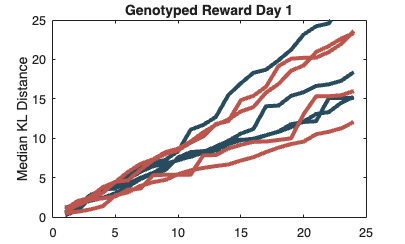

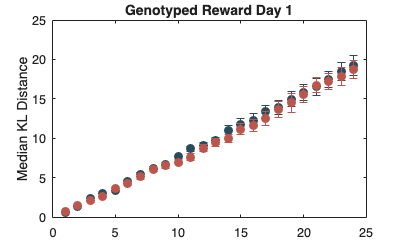

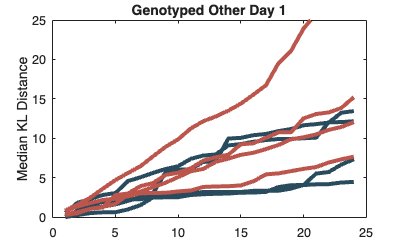

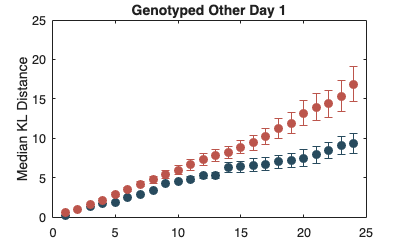

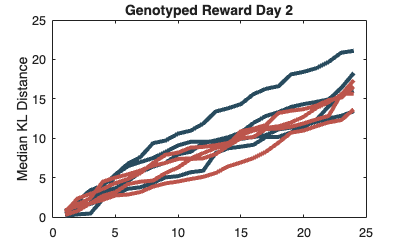

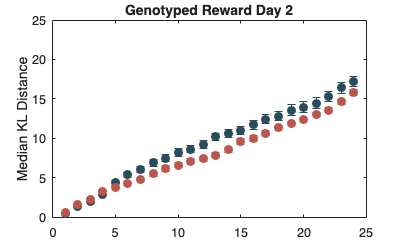

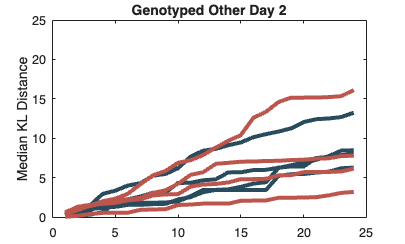

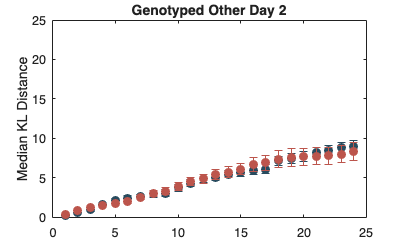

cumsum_days = nan(2,24*6);
cumsum_errors = nan(2,24*6);

for s = 1:session
    for a = 1:animals
        arrays = m_population_reward{s,a};
        arrays_other = m_population_other{s,a};
        if isempty(arrays)

            grouped_r(a,:) = nan(1,24);
        else
            grouped_r(a,:) = arrays;
        end

        if isempty(arrays_other)

            grouped_other(a,:) = nan(1,24);
        else
            grouped_other(a,:) = arrays_other;
        end

    end

    %%%% Plot for reward cells %%%%
    name = sprintf('Genotyped Reward Day %d',s);


    avr_cont = mean(grouped_r(control,:),'omitnan');
    avr_exp = mean(grouped_r(experimental,:),'omitnan');

    error_cont = SE(grouped_r(control,:));
    error_exp = SE(grouped_r(experimental,:));

    % figure('Visible','off')
    figure
    e = errorbar(avr_cont,error_cont,'o',"MarkerFaceColor",colors{1},"MarkerEdgeColor",colors{1});
    e.Color = colors{1};
    hold on
    k = errorbar(avr_exp,error_exp,'o',"MarkerFaceColor",colors{2},"MarkerEdgeColor",colors{2});
    k.Color = colors{2};
    ylim([0 25])
    yticks(0:5:25)
    ylabel('Median KL Distance')
    title(name)

    save_figure(path,sprintf('Summary Genotyped Reward Day %d',s))
    % close
    
    %%%% Plot for other cells %%%%
    name = sprintf('Genotyped Other Day %d',s);

    avr_cont_o = mean(grouped_other(control,:),'omitnan');
    avr_exp_o = mean(grouped_other(experimental,:),'omitnan');

    error_cont_o = SE(grouped_other(control,:));
    error_exp_o = SE(grouped_other(experimental,:));

    % figure('Visible','off')
    figure
    e = errorbar(avr_cont_o,error_cont,'o',"MarkerFaceColor",colors{1},"MarkerEdgeColor",colors{1});
    e.Color = colors{1};
    hold on
    k = errorbar(avr_exp_o,error_exp_o,'o',"MarkerFaceColor",colors{2},"MarkerEdgeColor",colors{2});
    k.Color = colors{2};
    ylim([0 25])
    yticks(0:5:25)
    ylabel('Median KL Distance')
    title(name)

    save_figure(path,sprintf('Summary Genotyped Other Day %d',s))
    % close
    
    %%%% Group over days %%%%
    if s == 1
        cumsum_days(:,1:24) = [avr_cont;avr_exp];
        cumsum_errors(:,1:24) = [error_cont;error_exp];

        cumsum_days_o(:,1:24) = [avr_cont_o;avr_exp_o];
        cumsum_errors_o(:,1:24) = [error_cont_o;error_exp_o];
    else
        index = 24*(s-1);
        multiplier = cumsum_days(:,index);
        distance_continued = [avr_cont;avr_exp] + multiplier;
        cumsum_days(:,index+1:index+24) = distance_continued;

        % multiplier_error = cumsum_errors(:,index);
        % errors_continued = [error_cont;error_exp] + multiplier_error;
        errors_continued = [error_cont;error_exp];                          % Think this is correct?
        cumsum_errors(:,index+1:index+24) = errors_continued;

        multiplier_o = cumsum_days_o(:,index);
        distance_continued_o = [avr_cont_o;avr_exp_o] + multiplier_o;
        cumsum_days_o(:,index+1:index+24) = distance_continued_o;


        errors_continued_o = [error_cont_o;error_exp_o];                         
        cumsum_errors_o(:,index+1:index+24) = errors_continued_o;

    end
    
end

## Cumulative plot over days

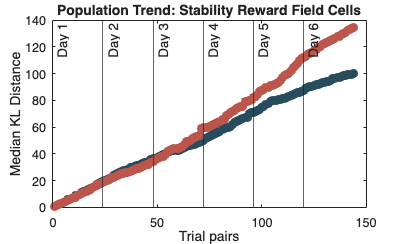

figure
e = errorbar(cumsum_days(1,:),cumsum_errors(1,:),'o',"MarkerFaceColor",colors{1},"MarkerEdgeColor",colors{1});
e.Color = colors{1};
hold on
k = errorbar(cumsum_days(2,:),cumsum_errors(2,:),'o',"MarkerFaceColor",colors{2},"MarkerEdgeColor",colors{2});
k.Color = colors{2};
xline([0,24,48,72,96,120],'-',{'Day 1','Day 2','Day 3','Day 4','Day 5','Day 6'});
xlabel('Trial pairs')
ylabel('Median KL Distance')
title('Population Trend: Stability Reward Field Cells')

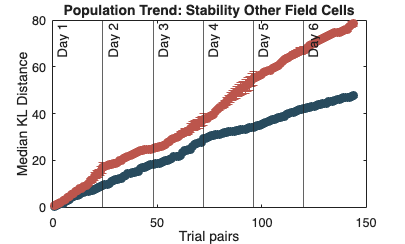


figure
e = errorbar(cumsum_days_o(1,:),cumsum_errors_o(1,:),'o',"MarkerFaceColor",colors{1},"MarkerEdgeColor",colors{1});
e.Color = colors{1};
hold on
k = errorbar(cumsum_days_o(2,:),cumsum_errors_o(2,:),'o',"MarkerFaceColor",colors{2},"MarkerEdgeColor",colors{2});
k.Color = colors{2};
xline([0,24,48,72,96,120],'-',{'Day 1','Day 2','Day 3','Day 4','Day 5','Day 6'});
xlabel('Trial pairs')
ylabel('Median KL Distance')
title('Population Trend: Stability Other Field Cells')

## Statistics

% Flatten all data into a table:
all_values = []; group = []; animal_mat = []; session = [];
for a = 1:animals
    for s = 1:6
        data = cumsum_reward{s,a}; 
        % data = cumsum_other{s,a};
        nCells = size(data,1);
        m_vals = median(data,2);  
        
        all_values = [all_values; m_vals];
        group = [group; repmat(a > 4, nCells, 1)];  % 0 for ctrl, 1 for exp
        animal_mat = [animal_mat; repmat(a, nCells, 1)];
        session = [session; repmat(s, nCells, 1)];
    end
end

T = table(all_values, group, animal_mat, session,'VariableNames', {'KL','Group','Animal','Session'});

% LMM: random intercept per animal
lme = fitlme(T, 'KL ~ Group + (1|Animal)');
disp(lme);


Linear mixed-effects model fit by ML

Model information:
    Number of observations             341
    Fixed effects coefficients           2
    Random effects coefficients          8
    Covariance parameters                2

Formula:
    KL ~ 1 + Group + (1 | Animal)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    2525.1    2540.4    -1258.6          2517.1  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF     pValue        Lower     Upper 
    {'(Intercept)'}        9.8819      0.72683    13.596    339    6.6708e-34    8.4522    11.312
    {'Group'      }        3.0819       1.0513    2.9316    339     0.0036017     1.014    5.1498

Random effects covariance parameters (95% CIs):
Group: Animal (8 Levels)
    Name1                  Name2                  Type           Estimate    Lower    Upper
  


% I think this is better: NB! intercept is day 1 in matlab syntax
T.Session = categorical(T.Session);
lme = fitlme(T, 'KL ~ Group*Session');
disp(lme);


Linear mixed-effects model fit by ML

Model information:
    Number of observations             341
    Fixed effects coefficients          12
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    KL ~ 1 + Group*Session

Model fit statistics:
    AIC     BIC       LogLikelihood    Deviance
    2522    2571.9    -1248            2496    

Fixed effects coefficients (95% CIs):
    Name                       Estimate    SE        tStat       DF     pValue        Lower      Upper 
    {'(Intercept)'    }          9.2618     1.567      5.9104    329    8.5332e-09     6.1791    12.344
    {'Group'          }          2.5616    2.4777      1.0339    329       0.30195    -2.3125    7.4358
    {'Session_2'      }         0.28226    2.3037     0.12252    329       0.90256    -4.2497    4.8142
    {'Session_3'      }        -0.60067    2.5098    -0.23933    329      


lme = fitlme(T, 'KL ~ Group*Session + (Session|Animal)');

## Compare Slopes

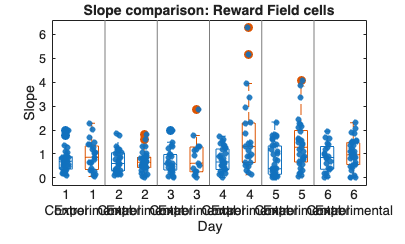

% combine all cells per group
session = 6;
slope = cell(session,2);
slope_other = cell(session,2);
p = nan(session,1); 
for s = 1:session

    % control cells - reward
    distances_contr = cell2mat(cumsum_reward(s,control)');
    [cell_numb,t] = size(distances_contr); % t does not change
    x = 1:t;
    for c = 1:cell_numb
        r = polyfit(x, distances_contr(c,:), 1);
        overall_slope = r(1); 
        slope{s,1}(c) = overall_slope;

    end
    ncells(s,1) = cell_numb;
    group_mat{s,1}(:,1) = repmat(s,cell_numb,1);
    
    
    % experimental cells - reward 
    distances_exp = cell2mat(cumsum_reward(s,experimental)');
    [cell_numb,~] = size(distances_exp);

    for c = 1:cell_numb
        r = polyfit(x, distances_exp(c,:), 1);
        overall_slope = r(1); 
        slope{s,2}(c) = overall_slope;

    end
    ncells(s,2) = cell_numb;
    group_mat{s,2}(:,1) = repmat(s,cell_numb,1);

    x1 = slope{s,1};
    x2 = slope{s,2};

    % Wilcoxon rank-sum test (Mann-Whitney U)
    p(s) = ranksum(x1, x2); 
    % [~,p(s)] = ttest2(x1, x2);

    %%%%%%%%%% Other Cells %%%%%%%%%
    % control cells
    distances_contr = cell2mat(cumsum_other(s,control)');
    [cell_numb,~] = size(distances_contr);
    x = 1:t;
    for c = 1:cell_numb
        r = polyfit(x, distances_contr(c,:), 1);
        overall_slope = r(1); 
        slope_other{s,1}(c) = overall_slope;

    end
    ncells_other(s,1) = cell_numb;
    group_mat_other{s,1}(:,1) = repmat(s,cell_numb,1);
    
    
    % experimental cells
    distances_exp = cell2mat(cumsum_other(s,experimental)');
    [cell_numb,~] = size(distances_exp);

    for c = 1:cell_numb
        r = polyfit(x, distances_exp(c,:), 1);
        overall_slope = r(1); 
        slope_other{s,2}(c) = overall_slope;

    end
    ncells_other(s,2) = cell_numb;
    group_mat_other{s,2}(:,1) = repmat(s,cell_numb,1);

    x1 = slope_other{s,1};
    x2 = slope_other{s,2};

    % Wilcoxon rank-sum test (Mann-Whitney U)
    p_other(s) = ranksum(x1, x2); 
    % [~,p_other(s)] = ttest2(x1, x2);



end

contr_cells = cell2mat(slope(:,1)')';
exp_cells = cell2mat(slope(:,2)')';

data = [contr_cells;exp_cells];

% Grouping variables
groups = [cell2mat(group_mat(:,1)); cell2mat(group_mat(:,2))];

type = [repmat({'Control'}, sum(ncells(:,1)), 1);repmat({'Experimental'}, sum(ncells(:,2)), 1)];

% Make grouped boxplot
figure
boxplot(data, {groups, type}, 'factorseparator', 1,'colors', lines(2), 'symbol', 'o')
ylabel('Slope')
xlabel('Day')
title('Slope comparison: Reward Field cells')
hold on
g = findgroups(groups, type);   
jit = 0.25*(rand(size(data))-0.5); 
scatter(g + jit, data, 20, 'filled', 'MarkerFaceAlpha', 0.9)
hold off

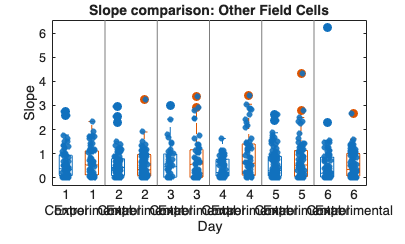


%%%%%%%%%% Other Cells %%%%%%%%%
contr_cells = cell2mat(slope_other(:,1)')';
exp_cells = cell2mat(slope_other(:,2)')';

data = [contr_cells;exp_cells];

% Grouping variables
groups = [cell2mat(group_mat_other(:,1)); cell2mat(group_mat_other(:,2))];

type = [repmat({'Control'}, sum(ncells_other(:,1)), 1);repmat({'Experimental'}, sum(ncells_other(:,2)), 1)];

% Make grouped boxplot
figure
boxplot(data, {groups, type}, 'factorseparator', 1,'colors', lines(2), 'symbol', 'o')
ylabel('Slope')
xlabel('Day')
title('Slope comparison: Other Field Cells')
hold on
g = findgroups(groups, type);   
jit = 0.25*(rand(size(data))-0.5); 
scatter(g + jit, data, 20, 'filled', 'MarkerFaceAlpha', 0.9)
hold off